# Linear Single-Track Vehicle Model

*by Ing. Denis Efremov*

## Introduction

The general single-track model discussed in the previous practice task is nonlinear. However, to implement any linear controller, we must obtain its linearization. Analogously to the aircraft industry, we can generally trim the nonlinear single-track model at any point in the state space to find a steady-state trajectory near this point. The single-track even could be linearized around some trajectory (when we need to control around it.) Those linearization strategies are mostly done using Taylor series and software like Matlab. Nevertheless, it is not today's topic because there is one linearization, mainly used to control lateral vehicle dynamics, which is a subject of that discussion. 

## Linear model derivation

To provide this linearization, let us assume the following vehicle dynamics (core dynamics from the nonlinear single-track):

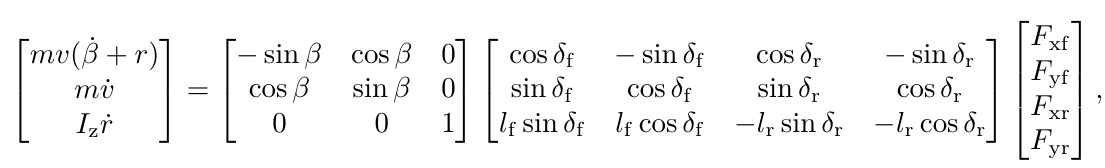

where states are:

- $v$ (m/s, magnitude of the velocity vector),

- $\beta$ (rad, sideslip angle),

- $r$ (rad/s, yaw rate, or how fast the vehicle rotates around its CG),

inputs are:

- $\delta_{\rm f}$ (rad, steering angle of the front axle),

- $\delta_{\rm r}$ (rad, steering angle of the rear axle),

parameters are:

- $I_{\rm z}$ (ks m2, moment of inertia),

- $m$ (kg, vehicle mass),

- $l_{\rm f}$ (m, CG-front axle distance),

- $l_{\rm r}$ (m, CG-rear axle distance).

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Task 1)** Using the assumption that the vehicle is driven with a constant velocity $v = v_{\rm c}$ and longitudinal traction forces are small $F_{\rm xf} \approx 0, F_{\rm xr} \approx 0$, try to linearize this system of equations. Choose linearization point at the origin ($\beta = 0, r = 0$).

 Tip 1: You will obtain only two state derivatives at the end because $\dot v = 0$.

 Tip 2: You can use the following approximations of trigonometrical functions:

- 
$$\sin x \approx x,$$


- 
$$\cos x \approx 1.$$


----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

Now you have a model where you still have lateral traction forces. However, they are depended on the model's states and inputs. Assume linear tire models:

- 
$$F_{\rm yf} = c_{\alpha \rm  f} \alpha_{\rm f},$$


- 
$$F_{\rm yr} = c_{\alpha \rm  r} \alpha_{\rm r},$$


which approximate lateral forces as linearly depended on the sideslip angle of a particular wheel. Assume also the following nonlinear equations for the sideslip angles:

- 
$$\alpha_{\rm f} = \delta_{\rm f} - \textnormal{atan} \frac{v_{\rm yf}}{v_{\rm xf}} = \delta_{\rm f} - \textnormal{atan} \frac{v \sin \beta + l_{\rm f} r}{v \cos \beta},$$


- 
$$\alpha_{\rm r} = \delta_{\rm r} - \textnormal{atan} \frac{v_{\rm yr}}{v_{\rm xr}} = \delta_{\rm r} - \textnormal{atan} \frac{v \sin \beta - l_{\rm r} r}{v \cos \beta}.$$


----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Task 2)** Try to derive linear approximations for sideslip angles using the same assumptions as in Task 1.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Task 3)** Write the linear model in a matrix form.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Task 4)** Implement a linear single-track model in the function below. Discuss the difference in outputs of the nonlinear and linear single-track models on a sine with dwell ride test.

load('lin_single_track_data.mat')
% initialize car parameters
initCar; 

% simulation time
start_time = time(1);
t_taken = time;

% states of the model will be stored here
betaode = zeros(length(time),1);
rode = zeros(length(time),1);

% ODE settings
options_ode = odeset('Maxstep', 10e-4, 'MaxOrder', 5, 'AbsTol', 1e-7);

% simulation
x_prev = [0, 0]; % init state
betaode(1) = x_prev(1);
rode(1) = x_prev(2);
for k = 1:length(time)-1
    u = [df(k), dr(k)];
    [~, x] = ode15s(@linear_single_track, [time(k) time(k+1)], x_prev, options_ode, u, car);
    betaode(k+1) = x(end,1);
    rode(k+1) = x(end,2);
    x_prev = x(end,:);
end

% plotting
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
plot(time, df, 'linewidth', 2)

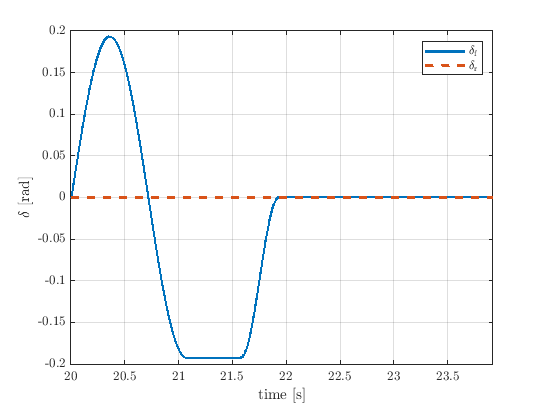

hold on
plot(time, dr, '--', 'linewidth', 2)
xlim([20, 23.92])
grid on
ylabel('$\delta$ [rad]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')
legend('$\delta_{\rm f}$', '$\delta_{\rm r}$', 'interpreter', 'latex')

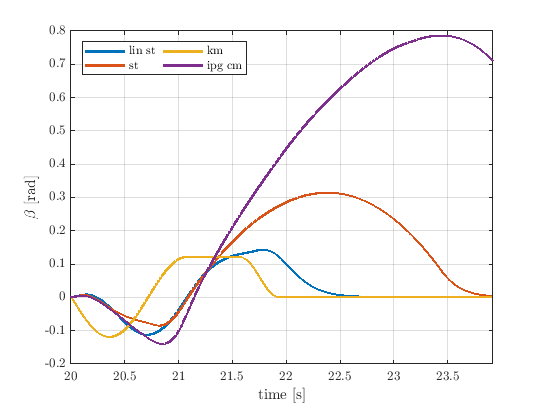


figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
plot(time, betaode, 'linewidth', 2)
hold on
plot(time, beta_st, 'linewidth', 2)
plot(time, beta_km, 'linewidth', 2)
plot(time, beta_cm, 'linewidth', 2)
xlim([20, 23.92])
grid on
ylabel('$\beta$ [rad]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')
legend('lin st', 'st', 'km', 'ipg cm', 'interpreter', 'latex','Location','northwest','NumColumns',2)

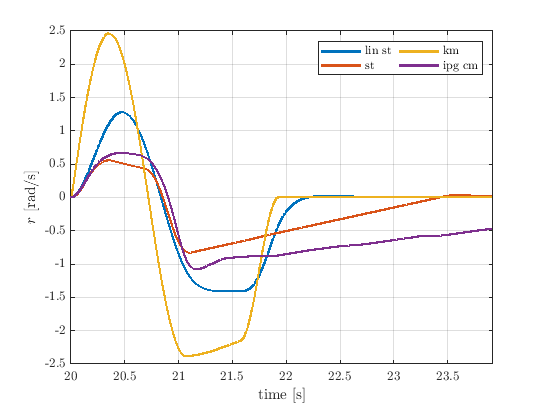


figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
plot(time, rode, 'linewidth', 2)
hold on
plot(time, r_st, 'linewidth', 2)
plot(time, r_km, 'linewidth', 2)
plot(time, r_cm, 'linewidth', 2)
xlim([20, 23.92])
grid on
ylabel('$r$ [rad/s]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')
legend('lin st', 'st', 'km', 'ipg cm', 'interpreter', 'latex','Location','northeast','NumColumns',2)

function xdot = linear_single_track(time, x, u, car)  
    % x = [beta, r] - states of the model
    % u = [df, dr] - inputs of the model
    % car = vehicle parameters
    beta = x(1);
    r = x(2);
    df = u(1);
    dr = u(2);
    lf = car.lf;
    lr = car.lr;
    v = car.v_const;
    m = car.m;
    alpha_f = df - beta - lf*r/v;
    alpha_r = dr - beta + lr*r/v;

    F_yf = car.Caf*alpha_f;
    F_yr = car.Car*alpha_r;

    beta_dot = (1/(m*v))*(F_yf*df+F_yr*dr)*beta - r + (1/(m*v))*(F_yf+F_yr);
    r_dot    = (1/car.Iz)*(F_yf*lf - F_yr*lr);
    xdot = [beta_dot; r_dot];
end